DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 8 iterations.
DRS converged in 8 iterations.
DRS converged in 7 iterations.
DRS converged in 6 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 9 iterations.
DRS converged in 8 iterations.
DRS converged in 8 iterations.
DRS converged in 7 iterations.
DRS converged in 5 iterations.
DRS conv

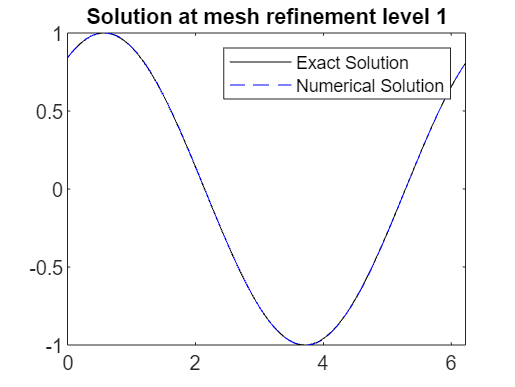

DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 4 iterations.
DRS converged in 5 iterations.
DRS converged in 4 iterations.
DRS converged in 4 iterations.
DRS converged in 3 iterations.
DRS converged in 1 iterations.
DRS conv

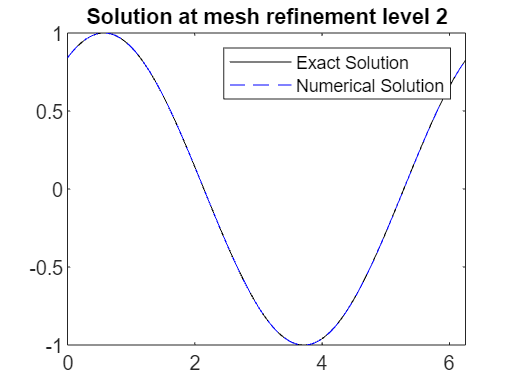

DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS conv

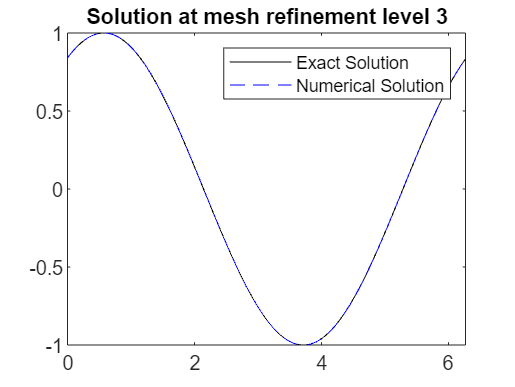

DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS conv

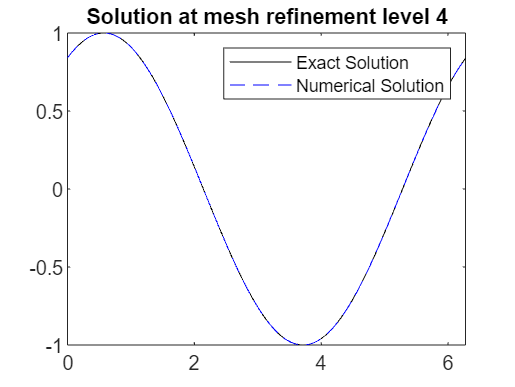

DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS converged in 1 iterations.
DRS conv

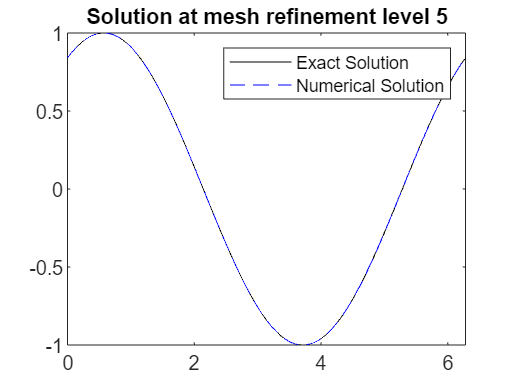

% Sanaz Hami
% 1D Linaear Advection integrated with Douglas-Rashford Splitting Function

% Initialization of parameters
xa = 0;
xb = 2 * pi;
T = 1;
m = -1; % Define lower bound
M = 1; % Define upper bound
lambda = 0.5; % Relaxation parameter for DR
epsilon = 1e-6; % Convergence criterion for DR
max_iter = 1000; % Maximum iterations for DR
v0 = @(x) sin(x); % Initial condition function
errtab = zeros(5, 2); % Error table initialization

% Main loop for mesh refinement
for kk = 1:5
    Nx = 100 * (2 ^ (kk - 1)) - 1; % Mesh size calculation
    h = (xb - xa) / (Nx + 1); % Spatial step size
    k = h^2; 
    v = zeros(1, Nx + 3); % Initialization of solution vector
    x = linspace(xa, xb - h, Nx + 1);
    v(2:Nx + 2) = v0(x); % Apply initial condition
    v(1) = v(Nx + 2); % Ghost point for the right boundary
    v(Nx + 3) = v(2); % Ghost point for the left boundary

    % Time marching
    for ii = 1:floor(T / k)
        v_new = zeros(size(v));
        for jj = 2:Nx + 2
            v_new(jj) = v(jj) + ((k / h) / 2) * (v(jj + 1) - v(jj - 1));
        end
        v_new(1) = v_new(Nx + 2); % Wrap-around for periodic boundary
        v_new(Nx + 3) = v_new(2); % Wrap-around for periodic boundary
        v = v_new;

        % Call DR function after each time step
        u_guess = v(2:Nx+2); % Use the current solution as the initial guess
        v(2:Nx+2) = DR(m, M, v(2:Nx+2), u_guess, epsilon, max_iter, lambda); % Post-process the solution
    end

    % Calculate numerical error
    u_exac = v0(x + T); % Exact solution at final time
    errtab(kk, 1) = sqrt(sum((u_exac - v(2:Nx + 2)).^2 * h)); % L2 norm error
    figure; % Create a new figure for each plot
    plot(x, u_exac, 'k-', x, v(2:Nx + 2), 'b--'); % Plot exact and numerical solutions
    legend('Exact Solution', 'Numerical Solution');
    title(sprintf('Solution at mesh refinement level %d', kk));
end


% Compute the order of accuracy
for kk = 2:5
    if errtab(kk - 1, 1) > 0
        errtab(kk, 2) = log(errtab(kk - 1, 1) / errtab(kk, 1)) / log(2);
    else
        errtab(kk, 2) = NaN; % If the previous error is 0, set the accuracy to NaN
    end
end

disp(errtab); % Display the error table with the order of accuracy

    0.0047         0
    0.0011    2.1217
    0.0005    1.1233
    0.0001    2.5995
    0.0000    1.7599




% End of mesh refinement loop

% Compute the order of accuracy
for kk = 2:5
    if errtab(kk - 1, 1) > 0
        errtab(kk, 2) = log(errtab(kk - 1, 1) / errtab(kk, 1)) / log(2);
    else
        errtab(kk, 2) = NaN; % If the previous error is 0, set the accuracy to NaN
    end
end

disp('Error table with the order of accuracy:');

Error table with the order of accuracy:


format shortE
disp(errtab); % Display the error table with the order of accuracy

   4.6672e-03            0
   1.0724e-03   2.1217e+00
   4.9227e-04   1.1233e+00
   8.1225e-05   2.5995e+00
   2.3984e-05   1.7599e+00

